# Variant of the Stroop Task on Auditory, Semantic and Chronic Stimuli

By Kelly Brennan, Jamie Cho, and Alix McCabe

## Loading all of the available data

addpath('C:\Users\kelly_000\OneDrive\Documents\Olin 2017\NeuroTech\NeuroTech-Project-2\data');
data_folder = dir('data')

data_folder = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


data_folder.name

ans = '.'

ans = '..'

ans = 'Data that doesn't work'

ans = 'stroop-subj1-run2.mat'

ans = 'stroop-subj2-run1.mat'

ans = 'stroop-subj3-run1.mat'

ans = 'stroop-subj4-run1.mat'

parse(data_folder(7).name)

ans = 120×1 cell array
    [ 687×4 single]
    [ 833×4 single]
    [ 514×4 single]
    [ 539×4 single]
    [ 438×4 single]
    [ 485×4 single]
    [ 308×4 single]
    [ 379×4 single]
    [ 481×4 single]
    [ 651×4 single]
    [ 529×4 single]
    [ 507×4 single]
    [ 537×4 single]
    [ 394×4 single]
    [ 497×4 single]
    [ 522×4 single]
    [ 404×4 single]
    [ 506×4 single]
    [ 502×4 single]
    [ 543×4 single]
    [ 432×4 single]
    [ 402×4 single]
    [ 365×4 single]
    [ 528×4 single]
    [ 504×4 single]
    [ 451×4 single]
    [ 589×4 single]
    [ 637×4 single]
    [ 724×4 single]
    [ 569×4 single]
    [ 456×4 single]
    [ 339×4 single]
    [ 758×4 single]
    [ 508×4 single]
    [ 450×4 single]
    [ 516×4 single]
    [ 498×4 single]
    [ 938×4 single]
    [ 625×4 single]
    [ 457×4 single]
    [ 381×4 single]
    [ 581×4 single]
    [ 484×4 single]
    [ 462×4 single]
    [ 388×4 single]
    [ 507×4 single]
    [ 450×4 single]
    [ 513×4 single]
    [ 381×4 singl

%[data_norm, stimulus_type, match_type, event_times] = [0,0,0,0]
[data_norm, stimulus_type, match_type, event_times] = parse(data_folder(4).name);
for i=5:7
    [data_norm_temp, stimulus_type_temp, match_type_temp, event_times_temp] = parse(data_folder(i).name);
    data_norm = vertcat(data_norm, data_norm_temp);
    stimulus_type = vertcat(stimulus_type,stimulus_type_temp);
    match_type = vertcat(match_type,match_type_temp);
    event_times = vertcat(event_times,event_times_temp);
    %[data_norm, stimulus_type, match_type, event_times; data_norm_temp, stimulus_type_temp, match_type_temp, event_times_temp]
end

%Setting up some global variables

match = data_norm{match_type == 1};
unmatch = data_norm{match_type == 0};
text_color = data_norm(stimulus_type == 1);
audio_text = data_norm(stimulus_type == 2);
color_audio = data_norm(stimulus_type == 3);

## Reaction Time

Reaction time defined as the time stamp from seeing the stimulus and the answe

RT_text_color = [];
RT_audio_text = []; 
RT_color_audio = []; 

ET_text_color = event_times(stimulus_type == 1);
ET_audio_text = event_times(stimulus_type == 2);
ET_color_audio = event_times(stimulus_type == 3);

for i = 1:size(ET_text_color)
   ET_temp = ET_text_color{i};
   RT_text_color(i,1) = ET_temp(end);
end
% RT_text_color

for i = 1:size(ET_audio_text)
   ET_temp = ET_audio_text{i};
   RT_audio_text(i,1) = ET_temp(end);
end
% RT_audio_text

for i = 1:size(ET_color_audio)
   ET_temp = ET_color_audio{i};
   RT_color_audio(i,1) = ET_temp(end);
end
% RT_color_audio

%RT_text_color = vertcat(RT_text_color,ET_text_color(1:end)(end))

We start by just plotting a histrogram of the reaction time and stimulus (AT, AC, CT) Or a box plot?

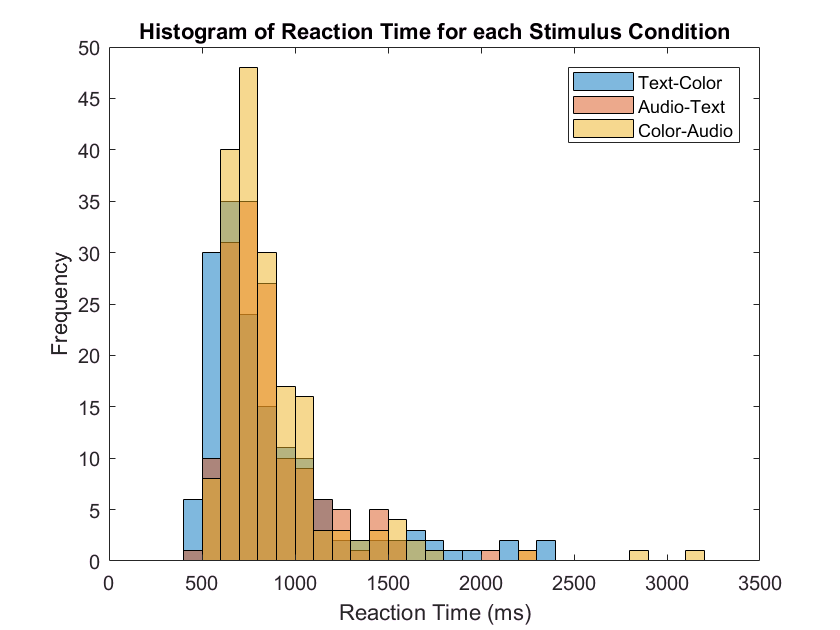

figure
binwidth = 100; %Since multiple histograms, we want to align the bin widths
facealpha = 0.5; %transparency of fill colors: 0 to 1
h1 = histogram(RT_text_color,'BinWidth',binwidth,'FaceAlpha',facealpha);
hold on; %make them on the same plot
h2 = histogram(RT_audio_text,'BinWidth',binwidth,'FaceAlpha',facealpha);
h3 = histogram(RT_color_audio,'BinWidth',binwidth,'FaceAlpha',facealpha);
ylabel('Frequency'); xlabel('Reaction Time (ms)'); title('Histogram of Reaction Time for each Stimulus Condition');
legend({'Text-Color','Audio-Text','Color-Audio'}); hold off;

Calculate the mean, median, mode, and std. of each stimulus condition

%Text-Color

RT_TC_mean = mean(RT_text_color)

RT_TC_mean = 853.4744

RT_TC_median = median(RT_text_color)

RT_TC_median = 726

RT_TC_mode = mode(RT_text_color)

RT_TC_mode = 560

RT_TC_std = std(RT_text_color)

RT_TC_std = 379.4516

RT_TC_var = var(RT_text_color)

RT_TC_var = 1.4398e+05

RT_TC_meanci = var(RT_text_color)

RT_TC_meanci = 1.4398e+05


RT_AC_mean = mean(RT_audio_text)

RT_AC_mean = 857.5417

RT_AC_median = median(RT_audio_text)

RT_AC_median = 786

RT_AC_mode = mode(RT_audio_text)

RT_AC_mode = 692

RT_AC_std = std(RT_audio_text)

RT_AC_std = 271.5180

RT_AC_var = var(RT_audio_text)

RT_AC_var = 7.3722e+04

RT_AC_meanci = var(RT_audio_text)

RT_AC_meanci = 7.3722e+04


RT_CA_mean = mean(RT_color_audio)

RT_CA_mean = 885.1444

RT_CA_median = median(RT_color_audio)

RT_CA_median = 788

RT_CA_mode = mode(RT_color_audio)

RT_CA_mode = 772

RT_CA_std = std(RT_color_audio)

RT_CA_std = 345.1847

RT_CA_var = var(RT_color_audio)

RT_CA_var = 1.1915e+05

RT_CA_meanci = var(RT_color_audio)

RT_CA_meanci = 1.1915e+05

ANOVA and effect size

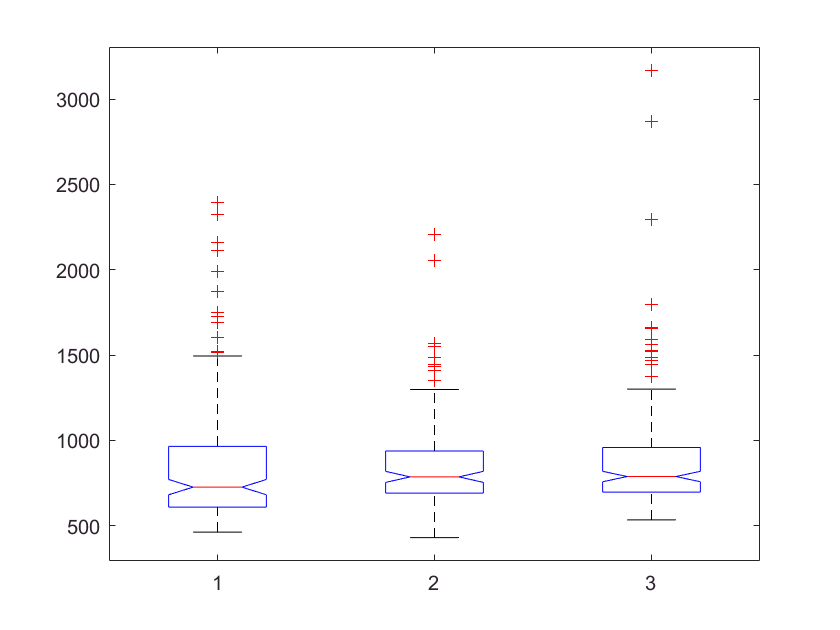

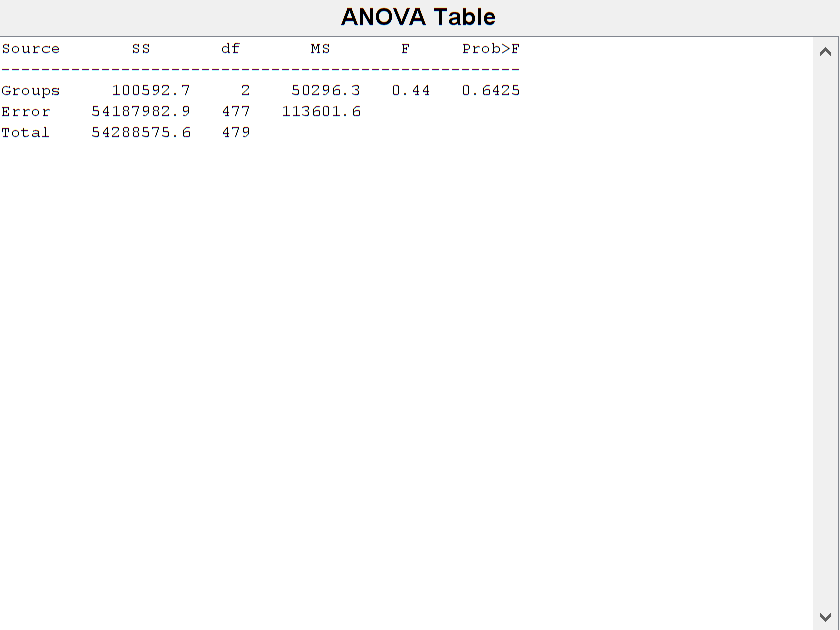

%Making a table
% T = table(RT_text_color, RT_audio_text, RT_color_audio);
max_RT_length = max([size(RT_text_color), size(RT_audio_text), size(RT_color_audio)]);

RT_text_color_expanded = [RT_text_color;NaN((max_RT_length(1) - length(RT_text_color)),1)];
RT_audio_text_expanded = [RT_audio_text;NaN((max_RT_length(1) - length(RT_audio_text)),1)];
RT_color_audio_expanded = [RT_color_audio;NaN((max_RT_length(1) - length(RT_color_audio)),1)];

[p, tbl, stats] = anova1([RT_text_color_expanded, RT_audio_text_expanded, RT_color_audio_expanded]);

etasquaredbetween = tbl{2,2}./tbl{4,2}

etasquaredbetween = 0.0019

Correlation of correctness and accuracy (maybe do some graphing? Can do more here)

sum(match_type(stimulus_type == 1))/length(match_type(stimulus_type == 1))

ans = 0.5128

sum(match_type(stimulus_type == 2))/length(match_type(stimulus_type == 2))

ans = 0.5278

sum(match_type(stimulus_type == 3))/length(match_type(stimulus_type == 3))

ans = 0.4667

% R1 = corrcoef(A,B)

%Repeat for the three conditions

## EEG Processing: P300 peaks

Defined as the time stamp from seeing the stimulus and P300. (We may be also cuious about P600 too).

Cleaning up the data --> See the "data_filtering.mat" script

Getting the peaks for each channel and condition:

Ch1_text_color_peak = max(mean(good_trials_Ch1(conditions_Ch1 == 1, :))) 

Ch1_text_color_peak = 16.7805

Ch1_audio_text_peak = max(mean(good_trials_Ch1(conditions_Ch1 == 2, :)))

Ch1_audio_text_peak = 17.5245

Ch1_color_audio_peak = max(mean(good_trials_Ch1(conditions_Ch1 == 3, :)))

Ch1_color_audio_peak = 18.3817


Ch2_text_color_peak = max(mean(good_trials_Ch2(conditions_Ch2 == 1, :))) 

Ch2_text_color_peak = 40.6066

Ch2_audio_text_peak = max(mean(good_trials_Ch2(conditions_Ch2 == 2, :)))

Ch2_audio_text_peak = 11.9190

Ch2_color_audio_peak = max(mean(good_trials_Ch2(conditions_Ch2 == 3, :)))

Ch2_color_audio_peak = 63.7515


Ch3_text_color_peak = max(mean(good_trials_Ch3(conditions_Ch3 == 1, :))) 

Ch3_text_color_peak = 27.4518

Ch3_audio_text_peak = max(mean(good_trials_Ch3(conditions_Ch3 == 2, :)))

Ch3_audio_text_peak = 27.9034

Ch3_color_audio_peak = max(mean(good_trials_Ch3(conditions_Ch3 == 3, :)))

Ch3_color_audio_peak = 21.3797


Ch4_text_color_peak = max(mean(good_trials_Ch4(conditions_Ch4 == 1, :))) 

Ch4_text_color_peak = 23.0937

Ch4_audio_text_peak = max(mean(good_trials_Ch4(conditions_Ch4 == 2, :)))

Ch4_audio_text_peak = 16.2945

Ch4_color_audio_peak = max(mean(good_trials_Ch4(conditions_Ch4 == 3, :)))

Ch4_color_audio_peak = 27.1878

Creating a matrix and ploting the peaks for each channel and condition

%Rows = Ch; Col = condition
Peaks = [max(mean(good_trials_Ch1(conditions_Ch1 == 1, :))) max(mean(good_trials_Ch1(conditions_Ch1 == 2, :))) max(mean(good_trials_Ch1(conditions_Ch1 == 3, :)));
    max(mean(good_trials_Ch2(conditions_Ch2 == 1, :))) max(mean(good_trials_Ch2(conditions_Ch2 == 2, :))) max(mean(good_trials_Ch2(conditions_Ch2 == 3, :)));
    max(mean(good_trials_Ch3(conditions_Ch3 == 1, :))) max(mean(good_trials_Ch3(conditions_Ch3 == 2, :))) max(mean(good_trials_Ch3(conditions_Ch3 == 3, :)));
    max(mean(good_trials_Ch4(conditions_Ch4 == 1, :))) max(mean(good_trials_Ch4(conditions_Ch4 == 2, :))) max(mean(good_trials_Ch4(conditions_Ch4 == 3, :)))]

Peaks =    16.7805   17.5245   18.3817
   40.6066   11.9190   63.7515
   27.4518   27.9034   21.3797
   23.0937   16.2945   27.1878



C = categorical({'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4'})

C = 1×4 categorical array
     Channel 1      Channel 2      Channel 3      Channel 4 


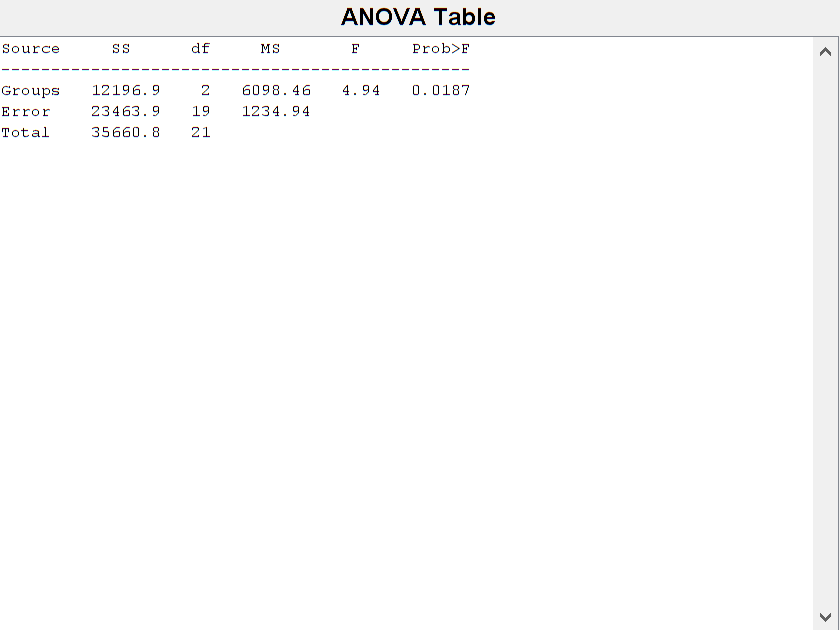

bar(C, Peaks)
legend('Text-Color', 'Audio-Text', 'Color-Audio')
ylabel('mV')

Creating the sample size matrix

%Will need to potentially photoshop this into the bar graph
N = [length(conditions_Ch1(conditions_Ch1 == 1)) length(conditions_Ch1(conditions_Ch1 == 2)) length(conditions_Ch1(conditions_Ch1 == 3));
    length(conditions_Ch2(conditions_Ch2 == 1)) length(conditions_Ch2(conditions_Ch2 == 2)) length(conditions_Ch2(conditions_Ch2 == 3));
    length(conditions_Ch3(conditions_Ch3 == 1)) length(conditions_Ch3(conditions_Ch3 == 2)) length(conditions_Ch3(conditions_Ch3 == 3));
    length(conditions_Ch4(conditions_Ch4 == 1)) length(conditions_Ch4(conditions_Ch4 == 2)) length(conditions_Ch4(conditions_Ch4 == 3))]

N =     14    13    12
     6     8     8
    11    10    17
    12    16    12


Channel 1 Anova

p = 0.6620

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'          'F'         'Prob>F'
    'Groups'    [  338.7739]    [ 2]    [169.3869]    [0.4173]    [0.6620]
    'Error'     [1.4614e+04]    [36]    [405.9456]          []          []
    'Total'     [1.4953e+04]    [38]            []          []          []


stats = struct with fields:
    gnames: {3×1 cell}
         n: [14 13 12]
    source: 'anova1'
     means: [30.9341 28.5332 35.7865]
        df: 36
         s: 20.1481


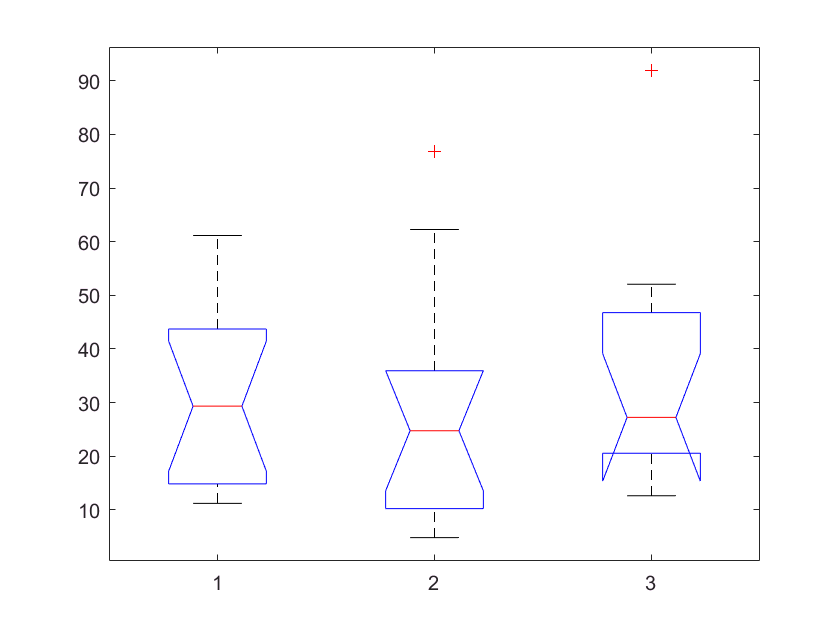

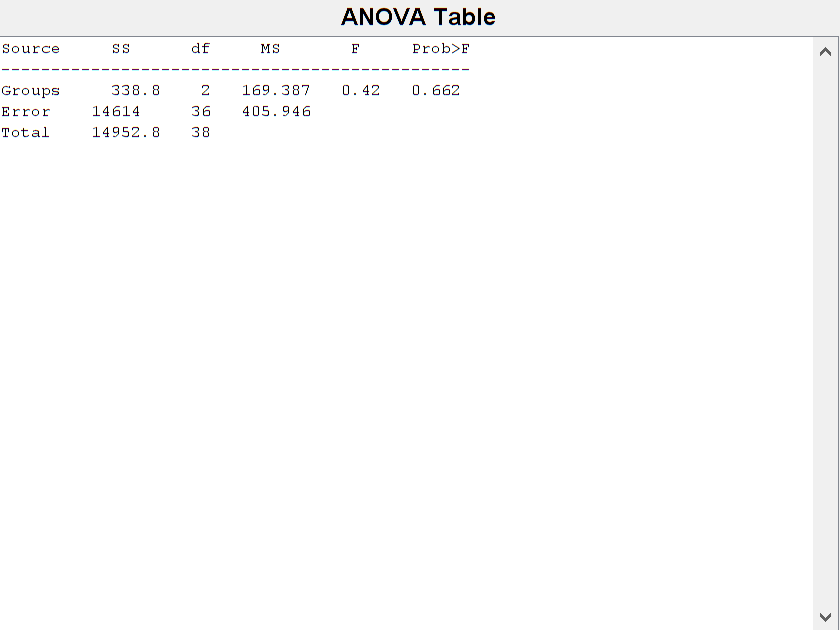

max_good_trials_Ch1_Con2_extended = [max(good_trials_Ch1((conditions_Ch1 == 2), :), [], 2, 'omitnan'); NaN(N(1,1) - N(1,2),1)];
max_good_trials_Ch1_Con3_extended = [max(good_trials_Ch1((conditions_Ch1 == 3), :), [], 2, 'omitnan'); NaN(N(1,1) - N(1,3),1)];

[p, tbl, stats] = anova1([max(good_trials_Ch1((conditions_Ch1 == 1), :), [], 2, 'omitnan'), max_good_trials_Ch1_Con2_extended, max_good_trials_Ch1_Con3_extended])

Channel 2 Anova

p = 0.0187

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'            'F'         'Prob>F'
    'Groups'    [1.2197e+04]    [ 2]    [6.0985e+03]    [4.9383]    [0.0187]
    'Error'     [2.3464e+04]    [19]    [1.2349e+03]          []          []
    'Total'     [3.5661e+04]    [21]              []          []          []


stats = struct with fields:
    gnames: {3×1 cell}
         n: [6 8 8]
    source: 'anova1'
     means: [51.9342 20.1731 75.2150]
        df: 19
         s: 35.1417


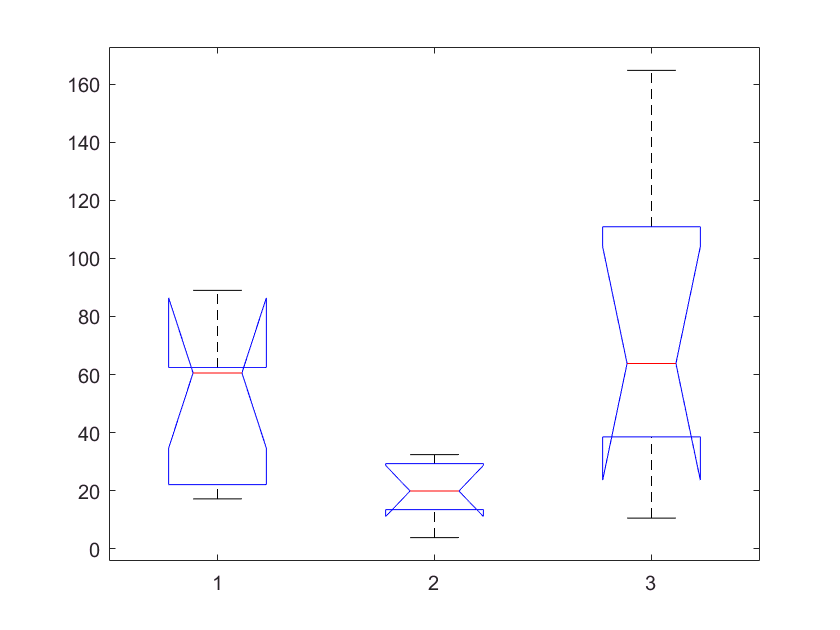

max_good_trials_Ch2_Con1_extended = [max(good_trials_Ch2((conditions_Ch2 == 1), :), [], 2, 'omitnan'); NaN(N(2,2) - N(2,1),1)];

[p, tbl, stats] = anova1([max_good_trials_Ch2_Con1_extended, max(good_trials_Ch2((conditions_Ch2 == 2), :), [], 2, 'omitnan'), max(good_trials_Ch2((conditions_Ch2 == 3), :), [], 2, 'omitnan')])

Channel 3 Anova

p = 0.9060

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'          'F'         'Prob>F'
    'Groups'    [  138.6727]    [ 2]    [ 69.3364]    [0.0990]    [0.9060]
    'Error'     [2.4517e+04]    [35]    [700.4976]          []          []
    'Total'     [2.4656e+04]    [37]            []          []          []


stats = struct with fields:
    gnames: {3×1 cell}
         n: [11 10 17]
    source: 'anova1'
     means: [41.2946 37.1153 37.0634]
        df: 35
         s: 26.4669


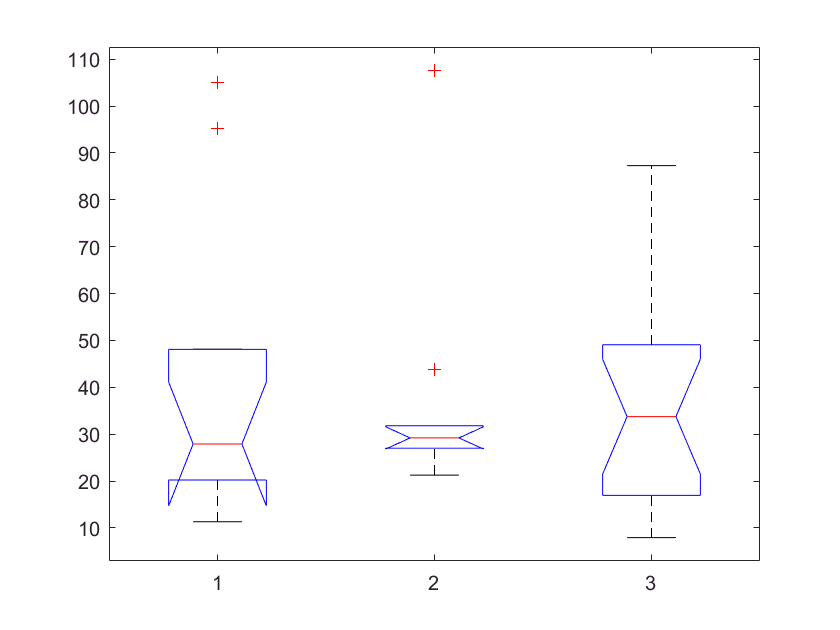

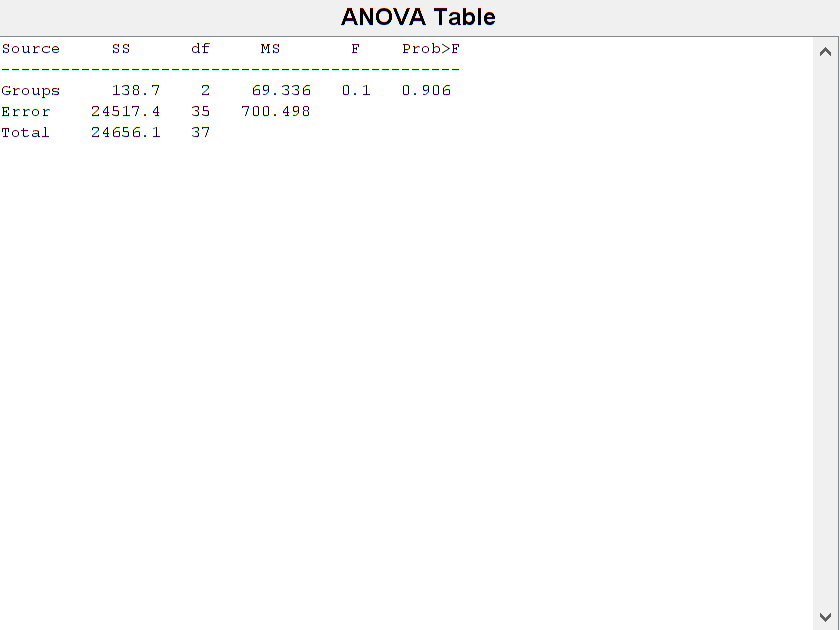

max_good_trials_Ch3_Con1_extended = [max(good_trials_Ch3((conditions_Ch3 == 1), :), [], 2, 'omitnan'); NaN(N(3,3) - N(3,1),1)];
max_good_trials_Ch3_Con2_extended = [max(good_trials_Ch3((conditions_Ch3 == 2), :), [], 2, 'omitnan'); NaN(N(3,3) - N(3,2),1)];

[p, tbl, stats] = anova1([max_good_trials_Ch3_Con1_extended, max_good_trials_Ch3_Con2_extended, max(good_trials_Ch3((conditions_Ch3 == 3), :), [], 2, 'omitnan')])

Channel 4 ANOVA

p = 0.7942

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'          'F'         'Prob>F'
    'Groups'    [  319.1647]    [ 2]    [159.5823]    [0.2319]    [0.7942]
    'Error'     [2.5462e+04]    [37]    [688.1691]          []          []
    'Total'     [2.5781e+04]    [39]            []          []          []


stats = struct with fields:
    gnames: {3×1 cell}
         n: [12 16 12]
    source: 'anova1'
     means: [31.5951 28.3432 35.1556]
        df: 37
         s: 26.2330


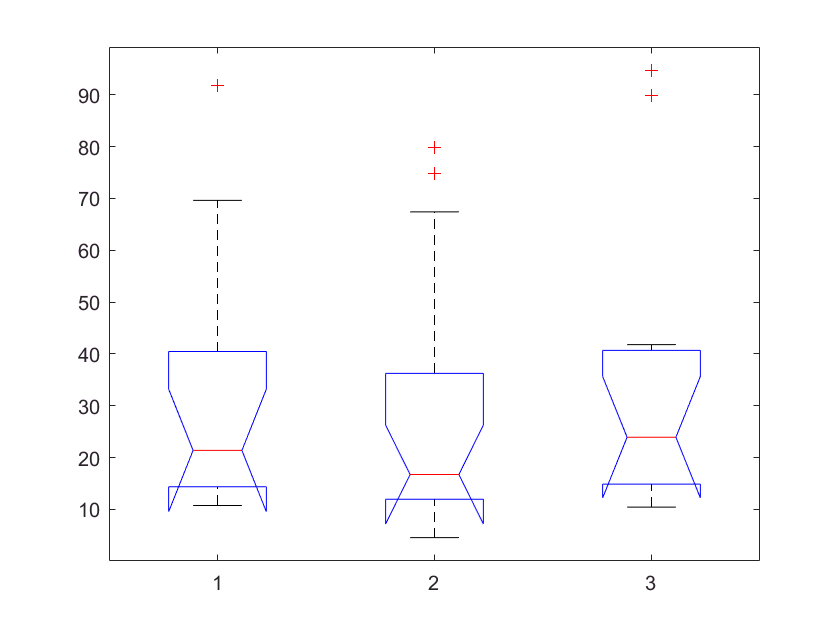

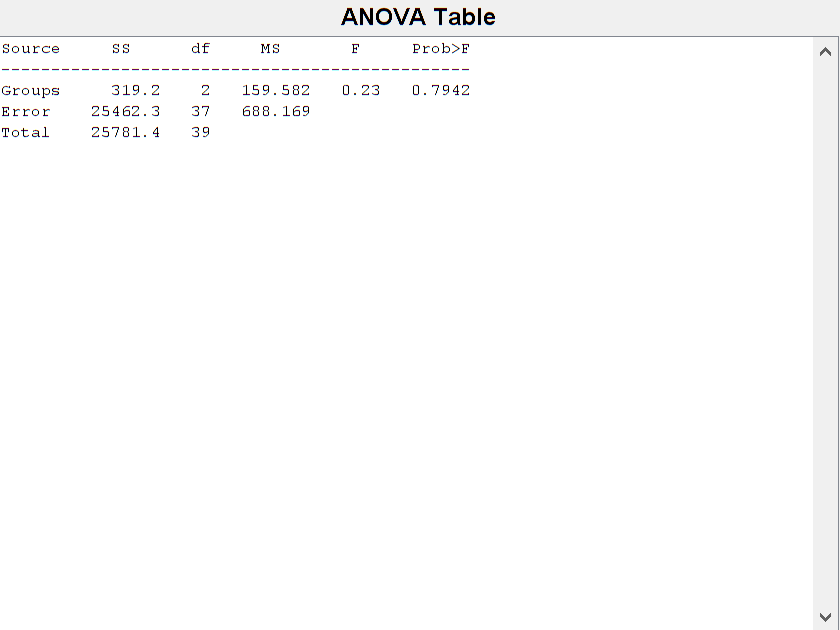

max_good_trials_Ch4_Con1_extended = [max(good_trials_Ch4((conditions_Ch4 == 1), :), [], 2, 'omitnan'); NaN(N(4,2) - N(4,1),1)];
max_good_trials_Ch4_Con3_extended = [max(good_trials_Ch4((conditions_Ch4 == 3), :), [], 2, 'omitnan'); NaN(N(4,2) - N(4,3),1)];

[p, tbl, stats] = anova1([max_good_trials_Ch4_Con1_extended, max(good_trials_Ch4((conditions_Ch4 == 2), :), [], 2, 'omitnan'), max_good_trials_Ch4_Con3_extended])

## Amplitude Intensity (and/our area under the curve)

Defined as the first definitive peak after exposure to the stimulus. Looking for a peak within a time range. 

Boxplot/historgram of the maximum amplitude with each stimulus condition

Calculate the mean, median, mode, and std. of each stimulus condition?

ANOVA & Effect size

How do the amplitudes correlate to reaction time?